# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

### Surface Laplace

The surface Laplacian is a spatial bandpass filter that increases topographical selectivity by effectively filtering out spatially broad features of the data.   

Spatially broad topographical features are likely to reflect volume-conducted potentials (see figure 22.1A) or distributed but highly coherent cortical sources. Surface Laplacian-transformed data estimate the potential at the dura (that is, if you could have electrodes under the skull instead of on top of the scalp), focus the results on high-spatial-frequency components while attenuating low-spatialfrequency components  

After application of the surface Laplacian transform, high-spatial-frequency activity—activity that is observable at only a small cluster of electrodes —is preserved, whereas low-spatial-frequency activity—activity that is observable at most or all electrodes — is attenuated  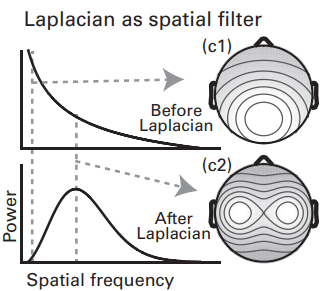

The surface Laplacian should be applied only to EEG (not MEG) data, and preferably to EEG data with 64 or more electrodes. 

### Advantages of surface Laplace

- the surface Laplacian improves **topographical localization ** 

- the surface Laplacian minimizes volume-conduction effects, which makes the surface Laplacian attractive for** electrode-level connectivity analyses**, including spectral coherence (Srinivasan et al. 2007b; Winter et al. 2007), phase-based synchronization measures (Lachaux et al. 1999), and Granger prediction (Cohen and van Gaal 2012; Seth 2010a).   

- the surface Laplacian is reference independent because it is computed based on the second spatial derivative of the potentials  

- the surface Laplacian requires few parameters or assumptions, including assumptions about the locations of brain sources that are measured by scalp electrodes.  

The main disadvantage of the surface Laplacian is a by-product of its advantage—spatially broad activities are attenuated and may become undetectable.  

### Technical points

-  Laplacian must be applied t**o time-domain data.** That is, you should compute the Laplacian first and then perform time-frequency analyses, not compute the Laplacian of time-frequency results.

- If you use the surface Laplacian only for improved topographical localization of an ERP effect, you can apply the surface Laplacian to the ERP rather than to the single-trial data because the ERP is a simple linear transformation of the single-trial data.   

- The surface Laplacian must be applied to all of the data or to none of the data; 

### **Algorithms for Computing the Surface Laplacian for EEG Data**   

APPROACH 1:

A basic approximation to the surface Laplacian is to subtract from each electrode the averaged activity of immediately surrounding electrodes (Hjorth 1975; Shepard 1968).  

APPROACH 2:

The spherical spline method by Perrin and colleagues (Perrin et al. 1987, 1989a, 1989b)  

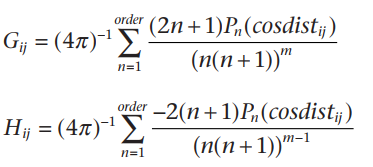

The first step in computing the Laplacian is to compute the *G *and *H *matrices. These are electrode-by-electrode weighting matrices that are used in the Laplacian computation.

The *G *and *H *matrices can be thought of as the weights that are applied to the data such that the activity at each electrode becomes a weighted sum (weighted by *G *and *H*, thus weighted by distance) of activity at all other electrodes.   

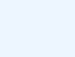

load sampleEEGdata.mat
% extract XYZ coordinates from EEG structure
X = [EEG.chanlocs.X];
Y = [EEG.chanlocs.Y];
Z = [EEG.chanlocs.Z];

chan1 = 'pz';
chan2 = 'c4';
chan3 = 'c3';

eucdist1 = zeros(1,64);
eucdist2 = zeros(1,64);
eucdist3 = zeros(1,64);

chan1idx = strcmpi(chan1,{EEG.chanlocs.labels});
chan2idx = strcmpi(chan2,{EEG.chanlocs.labels});
chan3idx = strcmpi(chan3,{EEG.chanlocs.labels});

for chani=1:EEG.nbchan
    eucdist1(chani) = sqrt( (EEG.chanlocs(chani).X-EEG.chanlocs(chan1idx).X)^2 + (EEG.chanlocs(chani).Y-EEG.chanlocs(chan1idx).Y)^2 + (EEG.chanlocs(chani).Z-EEG.chanlocs(chan1idx).Z)^2 );
    eucdist2(chani) = sqrt( (EEG.chanlocs(chani).X-EEG.chanlocs(chan2idx).X)^2 + (EEG.chanlocs(chani).Y-EEG.chanlocs(chan2idx).Y)^2 + (EEG.chanlocs(chani).Z-EEG.chanlocs(chan2idx).Z)^2 );
    eucdist3(chani) = sqrt( (EEG.chanlocs(chani).X-EEG.chanlocs(chan3idx).X)^2 + (EEG.chanlocs(chani).Y-EEG.chanlocs(chan3idx).Y)^2 + (EEG.chanlocs(chani).Z-EEG.chanlocs(chan3idx).Z)^2 );
end

hi_spatfreq  = 2*exp(- (eucdist1.^2)/(2*95^2) ); 
lo_spatfreq  =   exp(- (eucdist2.^2)/(2*50^2) )  +  exp(- (eucdist3.^2)/(2*50^2) );
surf_lap_all = laplacian_perrinX(hi_spatfreq+lo_spatfreq,X,Y,Z);

figure
subplot(221)
topoplot(hi_spatfreq,EEG.chanlocs,'plotrad',.53);
title('Low spatial frequency feature')

subplot(222)
topoplot(lo_spatfreq,EEG.chanlocs,'plotrad',.53);
title('High spatial frequency features')

subplot(223)
topoplot(hi_spatfreq+lo_spatfreq,EEG.chanlocs,'plotrad',.53);
title('Low+high features')

subplot(224)
topoplot(surf_lap_all,EEG.chanlocs,'plotrad',.53);
title('Laplacian of low+high features')

Further reading at page 281.

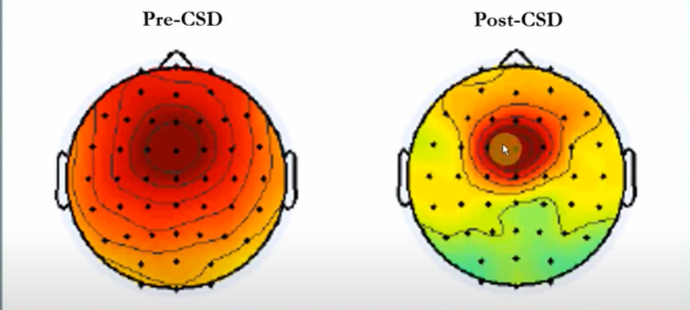

Exercise

- Perform a time-frequency decomposition of the data from those two electrodes both before and after computing the surface Laplacian (that is, compute the surface Laplacian on the raw data before applying a time-frequency decomposition). Compute both power (decibels normalized using a baseline period of your choice) 

- Plot the results using the same color scaling for before and after the surface Laplacian.

- Are there any salient differences in the time-frequency power or ITPC results before versus after application of the surface Laplacian, and do the differences depend on the frequency?

- How would you interpret similarities and differences at different frequency bands?  

### Principle Component Analysis

The goal of PCA is to construct sets of weights (called principal components) based on the covariance of a set of correlated variables (here, electrodes) so that components explain all of the variance of the data such that the components (1) are uncorrelated with each other and (2) are created so that the first principal component explains as much variance as possible for one variable.

For PCA, weights are defined only according to statistical properties of the data; physical electrode locations are not considered. The PCA and the surface Laplacian can be conceptualized as spatial filters that provide information about opposite sides of the spatial spectrum: whereas the surface Laplacian explicitly attenuates low-spatialfrequency activity and therefore highlights local features of the data, PCA highlights global spatial features of the data by identifying patterns of large-scale covariance.

The first step of computing a PCA is to construct a covariance matrix.  

in which *X *is an electrodes-by-time-points matrix (or, more generally, a variables-byinstances matrix), and *X *is the mean signal of each electrode over time.  

There are three ways to organize the data to apply equation. First, the covariance matrix can be computed** from the ERP.** Second, it can be computed from **all time points from all trials**, concatenated into a large 2-D matrix (in this case, 64 × 63,360 points, corresponding to 640 time points and 99 trials). Finally, the covariance matrix can be **computed separately for each trial**, and then the covariance matrices from each trial can be averaged together.  

This third approach is advantageous because it increases the signal-to-noise ratio of the covariance matrix.   

The covariance of the ERP can be conceptualized as reflecting the phase-locked (evoked) covariance, whereas the covariance of the single-trial EEG data can be conceptualized as reflecting the total (phase-locked and non-phase-locked) covariance.  

load sampleEEGdata.mat
% compute ERP
erp = squeeze(mean(EEG.data,3));

% subtract mean and compute covariance
erp = bsxfun(@minus,erp,mean(erp,2));
covar = (erp*erp')./(EEG.pnts-1);

figure
subplot(131)
imagesc(covar)
axis square
set(gca,'xticklabel',{EEG.chanlocs(get(gca,'xtick')).labels},'yticklabel',{EEG.chanlocs(get(gca,'ytick')).labels},'clim',[-1 5])
title('Covariance of ERP')


% one covariance of all timepoints
subplot(132)
eeg = reshape(EEG.data,EEG.nbchan,EEG.pnts*EEG.trials);
eeg = bsxfun(@minus,eeg,mean(eeg,2));
covar = (eeg*eeg')./(length(eeg)-1);
imagesc(covar)
axis square
set(gca,'xticklabel',{EEG.chanlocs(get(gca,'xtick')).labels},'yticklabel',{EEG.chanlocs(get(gca,'ytick')).labels},'clim',[20 150])
title('Covariance of single-trial EEG')


% average single-trial covariances
subplot(133)
covar = zeros(EEG.nbchan);
% note that the covariance of each trial is computed separately, then averaged
for i=1:EEG.trials
    eeg = bsxfun(@minus,squeeze(EEG.data(:,:,i)),squeeze(mean(EEG.data(:,:,i),2)));
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./i;
imagesc(covar)
axis square
set(gca,'xticklabel',{EEG.chanlocs(get(gca,'xtick')).labels},'yticklabel',{EEG.chanlocs(get(gca,'ytick')).labels},'clim',[20 150])
title('Average covariance of single-trial EEG')

Once a covariance matrix is computed, the next step is to perform an eigendecomposition via the Matlab function eig. An eigendecomposition is a matrix decomposition that returns eigenvectors and their associated eigenvalues, which characterize the patterns of interelectrode covariance. The results of the eigenvalue decomposition are square matrices with as many rows/ columns as there are variables (electrodes). Each column in the eigenvector matrix is a principal component, and each row stores the weights (also called component loadings) of each electrode.   

The electrode weights for** each component can be plotted as topographical maps**, and **time courses of the components can be obtained by multiplying the weights by the electrode time series data**. Note that this means that each component has one associated time course, and that time course is a weighted sum of the activity of all electrodes.

load sampleEEGdata.mat
% compute covariance of ERP
erp = squeeze(mean(EEG.data,3));
erp = bsxfun(@minus,erp,mean(erp,2));
covar = (erp*erp')./(EEG.pnts-1);

% principle components analysis via eigenvalue decomposition
[pc,eigvals] = eig(covar);

% components are listed in increasing order, and converted here to descending order for convenience
pc      = pc(:,end:-1:1);
eigvals = diag(eigvals);
eigvals = 100*eigvals(end:-1:1)./sum(eigvals); % convert to percent change

for i=1:9 % only first 6 are shown in the real figure
    figure(102)
    subplot(3,3,i)
    topoplot(double(pc(:,i)),EEG.chanlocs,'electrodes','off','plotrad',.53);
    title([ 'PC #' num2str(i) ', eigval=' num2str(eigvals(i)) ])

    figure(101)
    subplot(9,1,i)
    plot(EEG.times,pc(:,i)'*erp)
    hold on
    plot(get(gca,'xlim'),[0 0],'k')
    set(gca,'xlim',[-200 1200])
    title([ 'PC #' num2str(i) ', eigval=' num2str(eigvals(i)) ])
end

% average single-trial covariances
covar = zeros(EEG.nbchan);
for i=1:EEG.trials
    eeg = bsxfun(@minus,squeeze(EEG.data(:,:,i)),squeeze(mean(EEG.data(:,:,i),2)));
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./i;

% principle components analysis via eigenvalue decomposition
[pc,eigvals] = eig(covar);

% components are listed in increasing order, and converted here to descending order for convenience
pc      = pc(:,end:-1:1);
eigvals = diag(eigvals);
eigvals = 100*eigvals(end:-1:1)./sum(eigvals); % convert to percent change

for i=1:9 % only first 6 are shown in the real figure
    figure(10)
    subplot(3,3,i)
    topoplot(double(pc(:,i)),EEG.chanlocs,'electrodes','off','plotrad',.53);
    title([ 'PC #' num2str(i) ', eigval=' num2str(eigvals(i)) ])

    figure(11)
    subplot(9,1,i)
    
    % PC time course for each trial, then average together
    pctimes = zeros(1,EEG.pnts);
    for triali=1:EEG.trials
        eeg = bsxfun(@minus,squeeze(EEG.data(:,:,triali)),squeeze(mean(EEG.data(:,:,triali),2)));
        pctimes = pctimes + pc(:,i)'*eeg;
    end
    plot(EEG.times,pctimes./EEG.trials)
    hold on
    plot(get(gca,'xlim'),[0 0],'k')
    set(gca,'xlim',[-200 1200])
    title([ 'PC #' num2str(i) ', eigval=' num2str(eigvals(i)) ])
end


Although the two analyses were based on the same time-domain dataset, there are noticeable differences between them. One qualitative difference, for example, is that PC4 in panel B appears to be a bilateral sensorymotor component that is not apparent in the first six components of panel A. This may be because the data are stimulus locked; because the response time varies across trials, responserelated activity has little representation in the stimulus-locked ERP, although it is present in each trial.  

pcanum = 2; % 1 for panel A; 2 for panel B


% average single-trial covariances
covar = zeros(EEG.nbchan);
for i=1:EEG.trials
    eeg = bsxfun(@minus,squeeze(EEG.data(:,:,i)),squeeze(mean(EEG.data(:,:,i),2)));
    covar = covar + (eeg*eeg')./(EEG.pnts-1);
end
covar = covar./i;

% principle components analysis via eigenvalue decomposition
[pc,eigvals] = eig(covar);

% components are listed in increasing order, and converted here to descending order for convenience
pc      = pc(:,end:-1:1);
eigvals = diag(eigvals);
eigvals = 100*eigvals(end:-1:1)./sum(eigvals); % convert to percent change

pcadata = zeros(EEG.pnts,EEG.trials);
for i=1:EEG.trials
    pcadata(:,i) = pc(:,pcanum)'*bsxfun(@minus,squeeze(EEG.data(:,:,i)),squeeze(mean(EEG.data(:,:,i),2)));
end



min_freq =  2;
max_freq = 80;
num_frex = 30;

% define wavelet parameters
time = -1:1/EEG.srate:1;
frex = logspace(log10(min_freq),log10(max_freq),num_frex);
s    = logspace(log10(3),log10(10),num_frex)./(2*pi*frex);

% definte convolution parameters
n_wavelet            = length(time);
n_data               = EEG.pnts*EEG.trials;
n_convolution        = n_wavelet+n_data-1;
n_conv_pow2          = pow2(nextpow2(n_convolution));
half_of_wavelet_size = (n_wavelet-1)/2;

% get FFT of data
eegfft = fft(reshape(pcadata,1,EEG.pnts*EEG.trials),n_conv_pow2);

% initialize
eegpower = zeros(num_frex,EEG.pnts); % frequencies X time X trials

baseidx = dsearchn(EEG.times',[-500 -200]');

% loop through frequencies and compute synchronization
for fi=1:num_frex
    
    wavelet = fft( exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*(s(fi)^2))) , n_conv_pow2 );
    
    % convolution
    eegconv = ifft(wavelet.*eegfft);
    eegconv = eegconv(1:n_convolution);
    eegconv = eegconv(half_of_wavelet_size+1:end-half_of_wavelet_size);
    
    % Average power over trials
    temppower = mean(abs(reshape(eegconv,EEG.pnts,EEG.trials)).^2,2);
    eegpower(fi,:) = 10*log10(temppower./mean(temppower(baseidx(1):baseidx(2))));
end

figure
subplot(221)
topoplot(double(pc(:,pcanum)),EEG.chanlocs,'plotrad',.53);
subplot(222)
plot(EEG.times,mean(pcadata,2))
set(gca,'xlim',[-200 1200])

subplot(212)
contourf(EEG.times,frex,eegpower,40,'linecolor','none')
set(gca,'clim',[-3 3],'xlim',[-200 1000],'yscale','log','ytick',logspace(log10(min_freq),log10(max_freq),6),'yticklabel',round(logspace(log10(min_freq),log10(max_freq),6)*10)/10)
title([ 'TF power from component ' num2str(pcanum) ])


**Time-Resolved PCA**

So far, the covariance matrix used to compute the PCA was made from all time points. It may seem inappropriate to include all time points into the covariance matrix, particularly the buffer zones (for edge artifacts) or intertrial intervals. Furthermore, different time periods within the trial might be associated with different neuroelectrical modes or covariance configurations. Thus, PCA can be performed over successive time windows.  

whichcomp = 1; % 1 for panel A; 2 for panel B


centertimes = -200:50:1200;
timewindow  = 200; % ms on either side of center times
if whichcomp==1
    maptimes = [ -100 200 500 1000 ]; % times for plotting topomaps, based on visual inspection of PCA-coherence time courses
    clim     = [.08 .15]; % color limits also based on visual inspection
else
    maptimes = [ 0 300 750 1000 ];
    clim     = [-.2 .2]; % color limits also based on visual inspection
end



pcvariance = zeros(size(centertimes));
firstpcas  = zeros(length(centertimes),EEG.nbchan);

timesidx   = dsearchn(EEG.times',centertimes');
timewinidx = round(timewindow/(1000/EEG.srate));
mapsidx    = dsearchn(centertimes',maptimes');


for ti=1:length(centertimes)
    
    % temporally localized covariance
    covar = zeros(EEG.nbchan);
    for i=1:EEG.trials
        eeg = squeeze(EEG.data(:,timesidx(ti)-timewinidx:timesidx(ti)+timewinidx,i));
        eeg = bsxfun(@minus,eeg,mean(eeg,2));
        covar = covar + (eeg*eeg')./(EEG.pnts-1);
    end
    covar = covar./i;
    
    % principle components analysis via eigenvalue decomposition
    [pc,eigvals] = eig(covar);
    pc      = pc(:,end:-1:1);
    eigvals = diag(eigvals);
    eigvals = 100*eigvals(end:-1:1)./sum(eigvals); % convert to percent change
    
    pcvariance(ti)  = eigvals(whichcomp);
    firstpcas(ti,:) = pc(:,whichcomp);
end

figure
plot(centertimes,pcvariance)
xlabel('Time (ms)'), ylabel([ '% variance from PC' num2str(whichcomp) ])


figure
for i=1:length(maptimes)
    subplot(ceil(length(maptimes)/ceil(sqrt(length(maptimes)))),ceil(sqrt(length(maptimes))),i)
    topoplot(firstpcas(mapsidx(i),:),EEG.chanlocs,'plotrad',.53,'maplimits',clim);
    title([ 'PC' num2str(whichcomp) ' from ' num2str(maptimes(i)) ' ms' ]);
end

**Exercises**

1. Perform PCA on broadband data using two time windows, one before and one after trial onset (e.g., –500 to 0 ms and 100 to 600 ms).

2. Plot topographical maps and time courses of the first four components. To construct the PCA time courses, multiply the PCA weights defined by the pre- and posttrial time windows with the electrode time courses from the entire trial. Do you notice any differences in the topographical maps or time courses from before versus after stimulus onset? How would you interpret differences and/or similarities?

3. Repeat this exercise but after bandpass filtering in two different frequency bands. Make sure there are no edge artifacts in the pretrial time window (consider using reflection, if necessary, as described in figure 7.3). Justify your decision of frequency bands and time window width(s). Comment on any qualitative similarities and differences you observe between frequency bands and time windows and similarities and differences between the frequencyband-specific and broadband signal from the results obtained in the previous exercise.  